# Lab Session 3

**Multibody System Dynamics**

In this lab session we will talk about the equations of motion of a system using **dependent coordinates**. The central point of this approach are:

- **Lagrange multipliers**

## Equations of Motion

Let's consider a multibody system with a set of $m$ dependent coordinates ${\bf q}_{(m \times 1)}$ and a set of $r$ constraint equations


$${\bf \Phi} ({\bf q}) = {\bf 0}_{(r \times 1)}$$


Then, the lagrange equations can be written as:


$$\frac{d}{dt} \frac{\partial T}{\partial \bf \dot{q}} - \frac{\partial T}{\partial \bf q} = {\bf f}_\text{app} +  {\bf f}_\text{con}$$


where ${\bf f}_\text{app}$ contains the $m$ generalized forces applied to the system (e.g., gravity, spring, friction, etc.) and ${\bf f}_\text{con}$ contains the $m$ generalized constraint forces.

The generalized constraint forces can be written in terms of the constraint equations as follows:


$${\bf f}_\text{con} = \frac{\partial \phi_1}{\partial \bf q} \lambda_1 + \ldots + \frac{\partial \phi_r}{\partial \bf q} \lambda_r$$


where $\lambda_1 \ldots \lambda_r$ are the **lagrange multipliers** associated with the $r$ constraint equations $\phi_1 \ldots \phi_r$, which represent the constraint forces for each constraint equation. The constraint forces can be written in matrix form as


$${\bf f}_\text{con} 
= \left[ \frac{\partial \phi_1}{\partial \bf q} \cdots \frac{\partial \phi_r}{\partial \bf q} \right] \left[ \matrix{ \lambda_1 \cr \vdots \cr \lambda_r} \right]
= {\bf J}^\text{T} {\bf \lambda}$$


where ${\bf J}_{(r \times m)} = \frac{\partial \bf \Phi}{\partial \bf q}$ is the constraint Jacobian matrix.

Finaly, the matrix form of the lagrange equations can be written as:


$${\bf M} \ddot{\bf q} + {\bf c} = {\bf f}_\text{app} + {\bf J}^\text{T} {\bf \lambda}$$


clearvars
close all % windows
cd(fileparts(matlab.desktop.editor.getActiveFilename))
addpath("../models")
addpath("../source")

model = DoublePendulum();
system = model.initSystem();
viewer = model.initViewer([-2,2],[-2,2]);

Then, we create a `Simulation` of the `Model`.

sim = Simulation(model);

## Running a Simulation

First we need to setup the simulation properties: **start time**, **end time**, **time step**, and the kind of **integrator**.

sim.integrator  = "EulerDependent";
sim.timeStart   = 0;
sim.timeEnd     = 5;
sim.timeStep    = 0.01;

In addition, we can setup a storage to save the `System` data

storage = sim.initStorage();
storage.variables = ["cooInd", "velInd", "energyKin", "energyPot"];

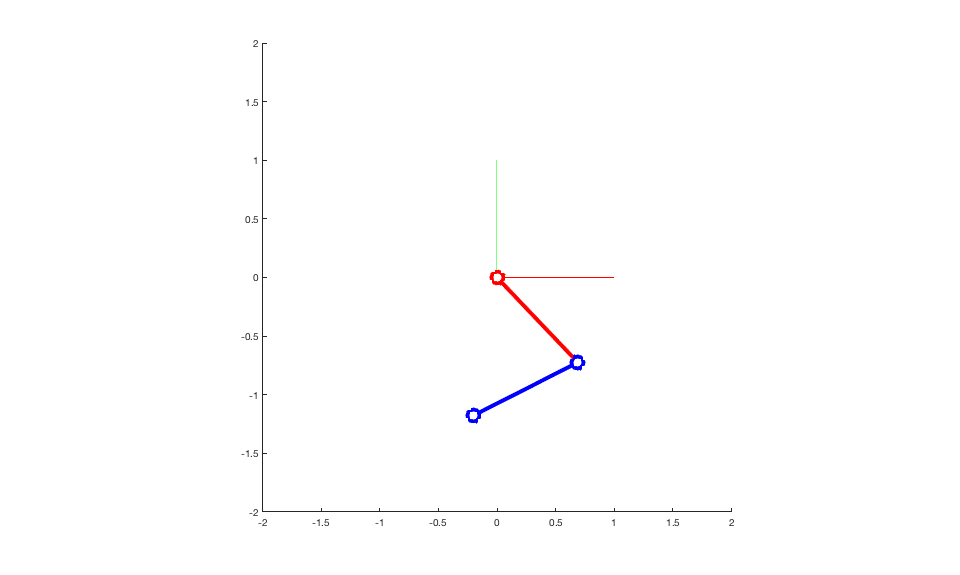

sim.initialize();
sim.run();

sim.storage.save("sim_results.csv")